cd F:\ResearchMainStream\0.ResearchBySection\C.动力学模型\参数优化\参数优化实现\ParallelSweepSimpack\结果分析组

clc
clear
close all


导入数据

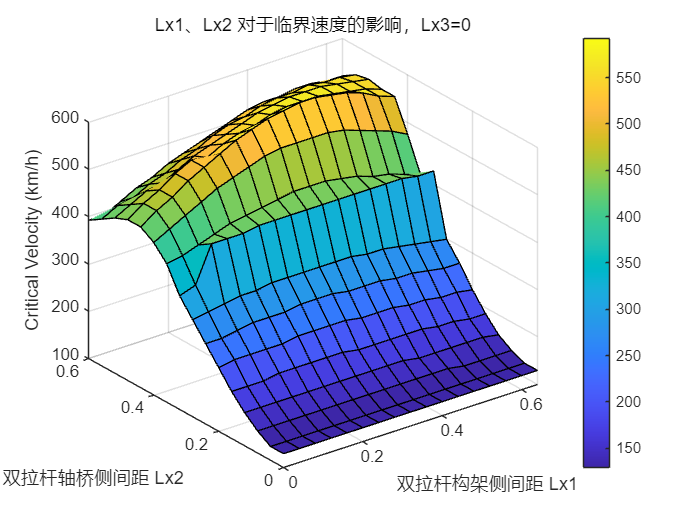

% Lx1~Lx3, 3264种组合

Xvar_L123 = readNPY('Xvars_027DIMs02.npy');
Rlt_7dims = readNPY('Result_027DIMs02.npy'); 


% 在 MATLAB 中重现同样的采样点
Lx1_sweep = 0 : 0.04 : 0.64;   % 17 个点
Lx2_sweep = 0 : 0.04 : 0.60;   % 16 个点
Lx3_sweep = -0.6 : 0.1 : 0.5;  % 12 个点

nLx1 = length(Lx1_sweep);  % 17
nLx2 = length(Lx2_sweep);  % 16
nLx3 = length(Lx3_sweep);  % 12

if nLx1 * nLx2 * nLx3 ~= length(Xvar_L123(1,:))
    disp("维度匹配错误")
    return;
end

% 设置容忍度 (tol)
tol = 1e-10;

% 找到 Lx3 “接近0” 的 Lx3 索引(Python不严格等于0)
index_Lx3_00 = find(abs(Xvar_L123(32, :) ) < tol);      % L3 = 0
index_Lx1_06 = find(abs(Xvar_L123(30, :) - 0.6) < tol); % L1 = 0.6 
index_Lx2_04 = find(abs(Xvar_L123(31, :) - 0.4) < tol); % L2 = 0.4 

% 临界速度, 按 {L1,L2,L3} = {0.6,0.4,0} 提取
CriticalVel_Lx3Eq00 = Rlt_7dims(1, index_Lx3_00);
CriticalVel_Lx1Eq06 = Rlt_7dims(1, index_Lx1_06);
CriticalVel_Lx2Eq04 = Rlt_7dims(1, index_Lx2_04);

% 刚性轮对磨耗数之和, 按 {L1,L2,L3} = {0.6,0.4,0} 提取
WearN_rigid_Lx3Eq00 = Rlt_7dims(2, index_Lx3_00);
WearN_rigid_Lx1Eq06 = Rlt_7dims(2, index_Lx1_06);
WearN_rigid_Lx2Eq04 = Rlt_7dims(2, index_Lx2_04);

% IRW 磨耗数之和, 按 {L1,L2,L3} = {0.6,0.4,0} 提取
WearNum_IRW_Lx3Eq00 = Rlt_7dims(4, index_Lx3_00);
WearNum_IRW_Lx1Eq06 = Rlt_7dims(4, index_Lx1_06);
WearNum_IRW_Lx2Eq04 = Rlt_7dims(4, index_Lx2_04);

%% reshape 成二维矩阵进行作图
CriticalVel_2D_L1L2 = reshape(CriticalVel_Lx3Eq00, [nLx2, nLx1]);
CriticalVel_2D_L1L3 = reshape(CriticalVel_Lx2Eq04, [nLx3, nLx1]);
CriticalVel_2D_L2L3 = reshape(CriticalVel_Lx1Eq06, [nLx3, nLx2]);


% 三维可视化 - A
% {Lx1, Lx2} -> 临界速度

figure();
[X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  % X大小: length(Lx2_sweep)-by-length(Lx1_sweep)
Z      = CriticalVel_2D_L1L2 * 3.6;              % 将criticalVel_m_s转置，以匹配X, Y大小
surf(X, Y, Z);                           % 绘制三维表面
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Critical Velocity (km/h)');
colorbar;     
title('Lx1、Lx2 对于临界速度的影响，Lx3=0')

function Plot7dimsFrom3264(Lx3, Xvar_L123, Rlt_7dims, Lx1_sweep, Lx2_sweep, nLx1, nLx2)

    % 找到 Lx3 “接近0” 的 Lx3 索引 (Python不严格等于0)
    tol = 1e-10;
    index_Lx3 = find(abs(Xvar_L123(32, :) - Lx3 ) < tol);      % L3 = Lx3

    % DDR = Data Dimension Reduction, 以标识是选取了给定L3取值的、筛选后的 Rlt_7dim
    Rlt_7dims_DDR = Rlt_7dims(:,index_Lx3);
    
    CriticalVel_2D_csv = reshape(Rlt_7dims_DDR(1,:), [nLx2, nLx1]); % 临界速度
    RigidSumWearNum_2D_csv  = reshape(Rlt_7dims_DDR(2,:), [nLx2, nLx1]);  
    IRWSumWearNum_2D_csv  = reshape(Rlt_7dims_DDR(4,:), [nLx2, nLx1]);  
    SperlingY_2D_csv   = reshape(Rlt_7dims_DDR(6,:), [nLx2, nLx1]);
    SperlingZ_2D_csv   = reshape(Rlt_7dims_DDR(7,:), [nLx2, nLx1]);
    


    figure();
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  % X大小: length(Lx2_sweep)-by-length(Lx1_sweep)
    Z      = CriticalVel_2D_csv * 3.6;              % 将criticalVel_m_s转置，以匹配X, Y大小
    surf(X, Y, Z);                           % 绘制三维表面
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Critical Velocity (km/h)');
    colorbar;     
    title('Lx1、Lx2 对于临界速度的影响, Lx3=0')

    figure();
    subplot(2,1,1)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep); 
    Z      = RigidSumWearNum_2D_csv ;
    surf(X, Y, Z);             
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Total Wear Number (N)');
    colorbar;     
    title('Lx1、Lx2 对于总磨耗数的影响, 刚性轮对, Lx3=0')
    
    subplot(2,1,2)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep); 
    Z      = IRWSumWearNum_2D_csv ;
    surf(X, Y, Z);             
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Total Wear Number (N)');
    colorbar;     
    title('Lx1、Lx2 对于总磨耗数的影响, 独立轮对, Lx3=0')

    figure();
    subplot(2,1,1)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep); 
    Z      = SperlingY_2D_csv;              
    surf(X, Y, Z);                          
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Sperling Y ');
    colorbar;     
    title('Lx1、Lx2 对于 Sperling Y 的影响, Lx3=0')
    
    subplot(2,1,2)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  
    Z      = SperlingZ_2D_csv   ;         
    surf(X, Y, Z);                   
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Sperling Z ');
    colorbar;     
    title('Lx1、Lx2 对于 Sperling Z 的影响, Lx3=0')
end


## 根据不同仿真、测试结果，调用局部函数（7维度评价作图）

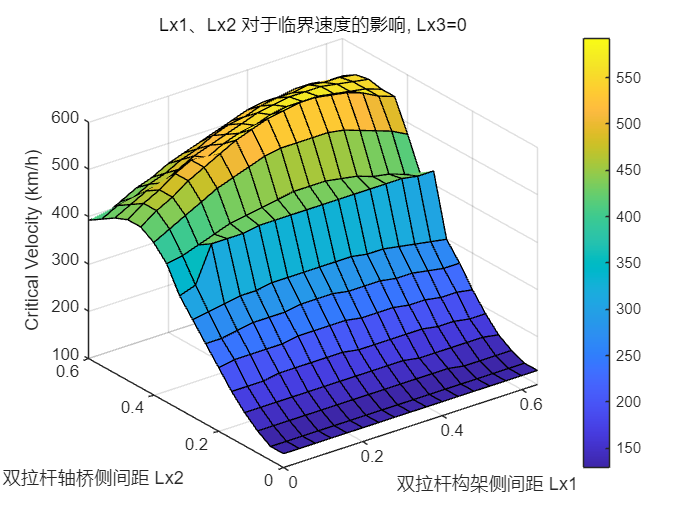

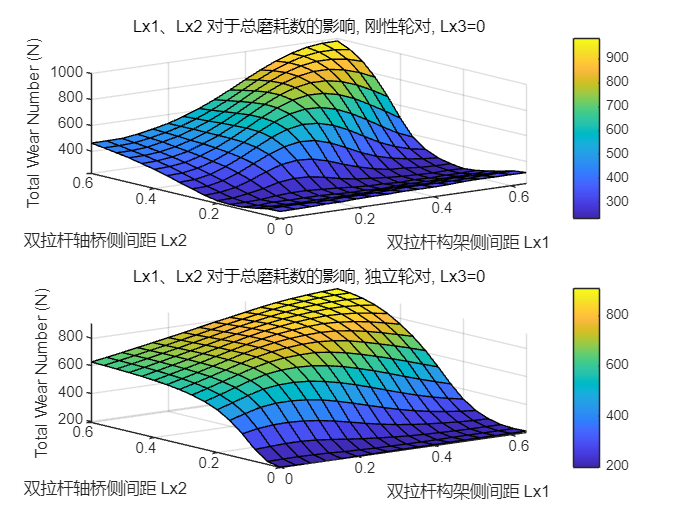

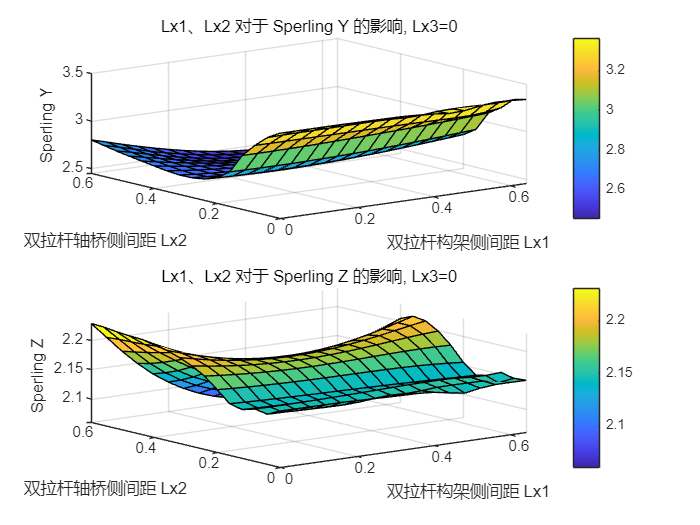

Plot7dimsFrom3264(0, Xvar_L123, Rlt_7dims, Lx1_sweep, Lx2_sweep, nLx1, nLx2)